# Transimpedance Amplifier Model

Purpose: The purpose of a transimpedance amplifier (TIA) is to convert an input current source into an output voltage. The value of the output voltage is dependent on the input current and the feedback resistance. The TIA is commonly used where there are very low currents, such as photodiodes. The TIA converts these very small currents into usable voltage. 

In DC operation, the output voltage can be calculated as: 

                                                                                                                    
$$V_{out} = -I_{in}R_f$$


Standard Modelling Techniques: 

The TIA consits of capacitors, resistors, an op-amp, and a photodiode. Using SimScape, we can model the TIA by importing the necessary capacitor, resistor, and op-amp blocks. Additionally, we need some support blocks such as the sine function block to inject a signal into the model, the solver configuration block, electrical reference blocks, a voltmeter block, a mux block, a to-workspace block, a scope block, a Simulink-PS Converter block, and a PS-Simulink Converter block.

By arranging the required blocks in the configuration specified by the project file within the Altium design file, we are able to inject different inputs into the simulation, and finally model the behaviour, relative to the data provided in the datasheet for a similar TIA.

Datasheet:

[https://www.mouser.ca/datasheet/2/389/tsv620-1852590.pdf](https://www.mouser.ca/datasheet/2/389/tsv620-1852590.pdf)

Figure 1:

- Offset voltage, $V_{io}$

- Common mode input voltage, $V_{icm}$ ** IS THIS THE RIGHT SYMBOL/VALUE?**

- Positive Voltage Source, $V_{CC+}$

Figure 2:

- Offset voltage, $V_{io}$

- Common mode input voltage, $V_{icm}$ ** IS THIS THE RIGHT SYMBOL/VALUE?**

- Positive Voltage Source, $V_{CC+}$

Figure 3:

- Supply voltage, $V_{CC}$

- Supply current, $I_{CC}$

- Common mode input voltage range, $V_{icm}$

Figure 4:

- Output current, $I_{out}$ **NO EXACT VARIABLE**

- Output voltage, $V_{out}$ **THERE IS HIGH AND LOW LEVEL**

- **Positive Voltage Source, **$V_{CC+}$

Figure 5:

- Output current, $I_{out}$ **NO EXACT VARIABLE**

- Output voltage, $V_{out}$ **THERE IS HIGH AND LOW LEVEL**

- **Positive Voltage Source, **$V_{CC+}$

## Datasheet Figures: 

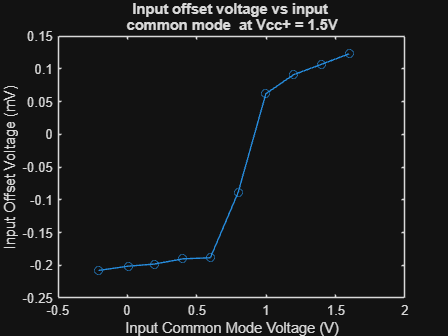

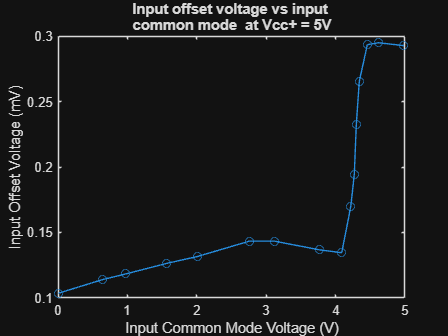

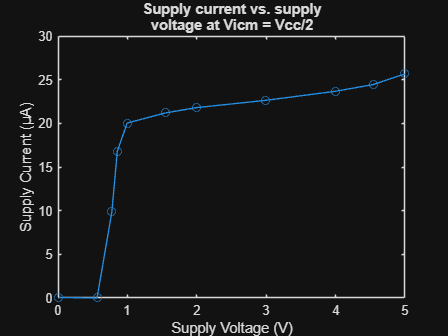

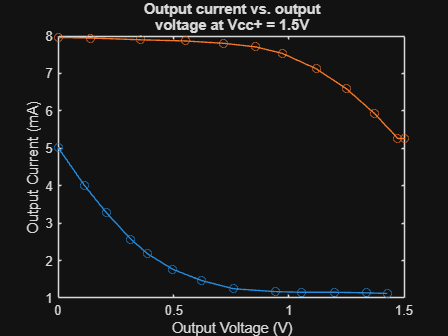

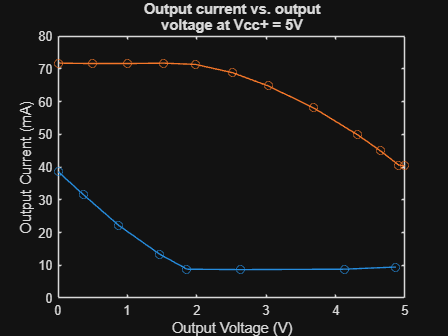

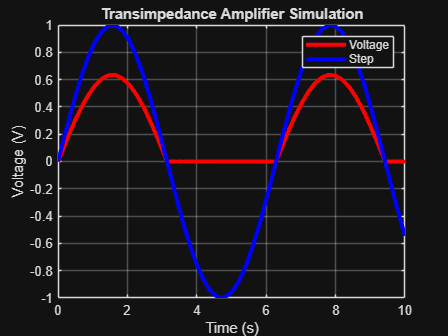

% Figure 1
fig1 = 'C:\Users\tp888\OneDrive\MATLAB\fig1.csv';
fig1Data = readtable(fig1);
fig1X = fig1Data.x;
fig1Y = fig1Data.y;
figure;
plot(fig1X, fig1Y, '-o');
xlabel('Input Common Mode Voltage (V)');
ylabel('Input Offset Voltage (mV)');
title({'Input offset voltage vs input ','common mode  at Vcc+ = 1.5V'});

% Figure 2
fig2 = 'C:\Users\tp888\OneDrive\MATLAB\fig2.csv';
fig2Data = readtable(fig2);
fig2X = fig2Data.x;
fig2Y = fig2Data.y;
figure;
plot(fig2X, fig2Y, '-o');
xlabel('Input Common Mode Voltage (V)');
ylabel('Input Offset Voltage (mV)');
title({'Input offset voltage vs input ','common mode  at Vcc+ = 5V'});

% Figure 3
fig3 = 'C:\Users\tp888\OneDrive\MATLAB\fig3.csv';
fig3Data = readtable(fig3);
fig3X = fig3Data.x;
fig3Y = fig3Data.y;
figure;
plot(fig3X, fig3Y, '-o');
xlabel('Supply Voltage (V)');
ylabel('Supply Current (µA)');
title({'Supply current vs. supply','voltage at Vicm = Vcc/2'});

% Figure 4
fig4a = 'C:\Users\tp888\OneDrive\MATLAB\fig4a.csv';
fig4b = 'C:\Users\tp888\OneDrive\MATLAB\fig4b.csv';
fig4aData = readtable(fig4a);
fig4bData = readtable(fig4b);
fig4aX = fig4aData.x;
fig4aY = fig4aData.y;
fig4bX = fig4bData.x;
fig4bY = fig4bData.y;
figure;
plot(fig4aX, fig4aY, '-o');
hold on;
plot(fig4bX, fig4bY, '-o');
hold off;
xlabel('Output Voltage (V)');
ylabel('Output Current (mA)');
title({'Output current vs. output','voltage at Vcc+ = 1.5V'});

% Figure 5
fig5a = 'C:\Users\tp888\OneDrive\MATLAB\fig5a.csv';
fig5b = 'C:\Users\tp888\OneDrive\MATLAB\fig5b.csv';
fig5aData = readtable(fig5a);
fig5bData = readtable(fig5b);
fig5aX = fig5aData.x;
fig5aY = fig5aData.y;

fig5bX = fig5bData.x;
fig5bY = fig5bData.y;
figure;
plot(fig5aX, fig5aY, '-o');
hold on;
plot(fig5bX, fig5bY, '-o');
hold off;
xlabel('Output Voltage (V)');
ylabel('Output Current (mA)');
title({'Output current vs. output','voltage at Vcc+ = 5V'});